% Load data
rot = load("calib1_rotate.mat");
straight = load("calib2_straight.mat");

% Task 1
task1_1 = load("task1_1.mat");
task1_2 = load("task1_2.mat");
task1_3 = load("task1_3.mat");
task1_4 = load("task1_4.mat");
task1_5 = load("task1_5.mat");

% Task 2
task2_1 = load("task2_1.mat");
task2_2 = load("task2_2.mat");
task2_3 = load("task2_3.mat");
task2_4 = load("task2_4.mat");
task2_5 = load("task2_5.mat");

## Task 1: Straight-Line Drive

a. The robot moves forward and backward in a straight line at known intervals.

b. Your algorithm must accurately estimate position and yaw during these simple movements.

#### Calibration

- Use mean-squared error to calculate sensor offset with first 60 seconds of stationary data

- GT for ToF is straight position data, for magnetometer is straight rotation data

- ToF Calibration:

- Magnetometer Calibration: unit conversion, bias removal, ellipsoid method   


$$\begin{array}{l}
y_{\textrm{calibrated}} =y+b\\
\textrm{where},\\
y_i =\textrm{raw}\;\textrm{sensor}\;\textrm{reading}\\
x_i =\textrm{ground}\;\textrm{truth}\;\textrm{position}\\
b=\textrm{bias}\;\textrm{or}\;\textrm{offset}
\end{array}$$


Using least-squares to calibrate:


$$\min_b \sum_i^{N-1} ||y_i +b-x_i ||^2$$


simplifies to:


$$b=\textrm{mean}\left(x-y\right)$$


%% LOAD DATA %%
% Time (straight)
time_straight = straight.out.GT_time.time;
idx_straight = find(time_straight==60); % Marks one minute of stationary before movement

% Ground Truth Position
GT_calib_straight_pos = straight.out.GT_position.signals.values;

% Position sensors
SS_calib_straight_ToF1 = straight.out.Sensor_ToF1.signals.values;
SS_calib_straight_ToF2 = straight.out.Sensor_ToF2.signals.values;
SS_calib_straight_ToF3 = straight.out.Sensor_ToF3.signals.values;

% Time (Rotation)
time_rot = rot.out.GT_time.time;
idx_rot = find(time_rot==60);

% Ground Truth Rotation
GT_calib_rot = rot.out.GT_rotation.signals.values;

% Yaw sensors
SS_calib_rot_magnet = squeeze(rot.out.Sensor_MAG.signals.values)';
SS_calib_rot_accel = squeeze(rot.out.Sensor_ACCEL.signals.values)';

%% CALIBRATION %%
% Calibration for ToF sensor readings (position)
offset_ToF1 = mean(SS_calib_straight_ToF1(:,1)-GT_calib_straight_pos(:,1));
offset_ToF2 = mean(SS_calib_straight_ToF2(:,1)-GT_calib_straight_pos(:,2));
offset_ToF3 = mean(SS_calib_straight_ToF2(:,3)-GT_calib_straight_pos(:,3));

% Calibration for magnetometer (yaw)
% B = magnetic field
mag_raw_2D = [SS_calib_rot_magnet(:,2), SS_calib_rot_magnet(:,3)];
[mag_cal, params] = calibrateMagnetometer2D(mag_raw_2D)

mag_cal =     3.7660   -0.4423
    3.7660   -0.4423
    3.7660   -0.4423
    3.7660   -0.4423
   -0.6869    0.7263
   -0.6869    0.7263
   -0.6716    0.7399
   -0.6716    0.7399
   -0.6716    0.7399
   -0.6716    0.7399


params = struct with fields:
            offset: [-5.3266e-05 6.4285e-05]
    softIronMatrix: [2×2 double]
          rotation: [2×2 double]
           scaling: [2×2 double]
           ellipse: [0.1177 -0.3966 1.5953 1.4834 -0.6888]



% x = mag_raw_2D(:,1);
% y = mag_raw_2D(:,2);
% D = [x.^2, x.*y, y.^2, x, y, ones(size(x))];  % Design matrix
% S = D' * D;                                   % Scatter matrix
% 
% % Solve generalized eigenvalue problem
% [~, ~, V] = svd(S);
% a = V(:,end);  % Ellipse coefficients
% % Extract parameters from conic: Ax^2 + Bxy + Cy^2 + Dx + Ey + F = 0
% A = a(1); B = a(2); C = a(3); D = a(4); E = a(5); F = a(6);
% 
% % Algebraic formula for center of conic section
% delta = B^2 - 4*A*C;
% x0 = (2*C*D - B*E) / delta;
% y0 = (2*A*E - B*D) / delta;
% offset = [x0, y0];  % Hard-iron correction
% 
% % Shift data to origin
% centered = mag_raw_2D - offset;
% 
% % Covariance gives ellipse shape
% C = cov(centered);
% 
% % Compute whitening matrix
% [V, D] = eig(C);
% W = V * diag(1 ./ sqrt(diag(D))) * V';
% 
% % Apply full calibration
% mag_cal = (centered * W')';
% mag_cal = mag_cal';

#### Visualization

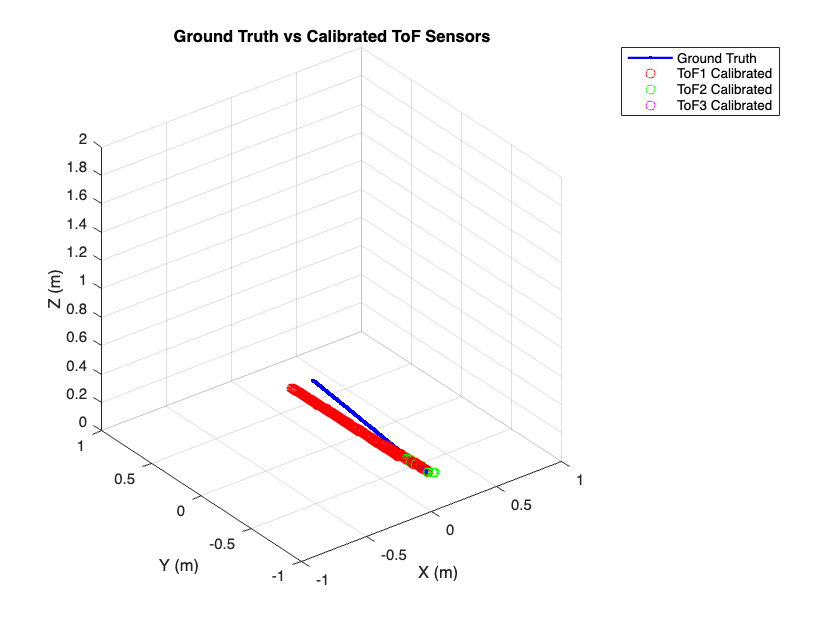

%% CHECK CALIBRATION WITH VISUALIZATION %%

% Check position calibration
% Plot Ground Truth
X = GT_calib_straight_pos(:,1);
Y = GT_calib_straight_pos(:,2);
Z = GT_calib_straight_pos(:,3);

figure;
plot3(X, Y, Z, 'b.-', 'LineWidth', 1.5); % Ground truth trajectory
hold on;
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Ground Truth vs Calibrated ToF Sensors');
grid on;
axis equal;

% Apply offset and plot ToF data
ToF1_corrected = SS_calib_straight_ToF1(:,1) - offset_ToF1;
ToF2_corrected = SS_calib_straight_ToF2(:,1) - offset_ToF2;
ToF3_corrected = SS_calib_straight_ToF2(:,3) - offset_ToF3;

% Plot corrected ToF data
plot3(ToF1_corrected, Y, Z, 'ro');
plot3(X, ToF2_corrected, Z, 'go');
plot3(X, Y, ToF3_corrected, 'mo');

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Ground Truth vs Calibrated ToF Sensors');

legend('Ground Truth', 'ToF1 Calibrated', 'ToF2 Calibrated', 'ToF3 Calibrated');

grid on;
axis equal;

% Optional: Manually set axis limits (adjust based on your actual data range)
xlim([-1 1]);
ylim([-1 1]);
zlim([0 2]);

view(3); % Enable 3D view

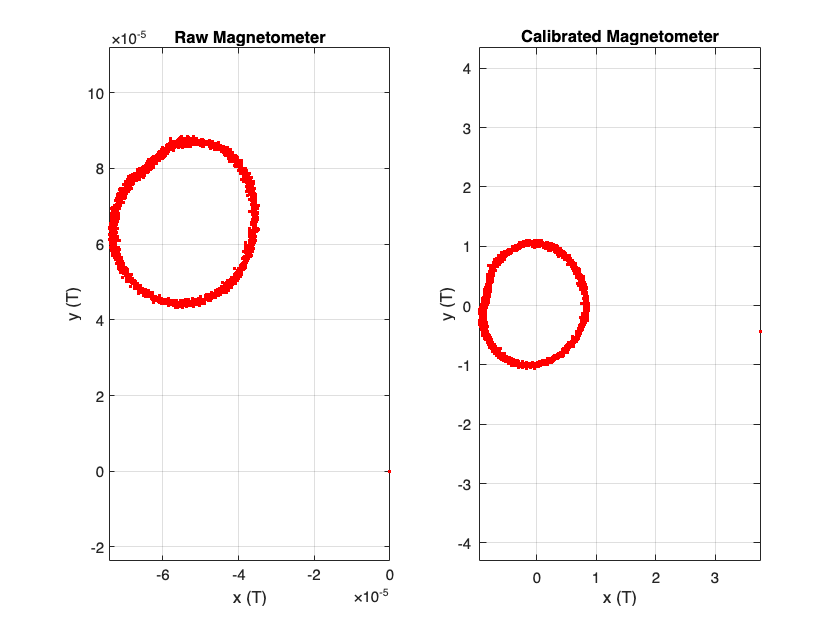


% Check yaw calibration
figure;
subplot(1,2,1); % Plot raw magnetometer ellipse
plot(mag_raw_2D(:,1), mag_raw_2D(:,2), 'r.');
xlabel('x (T)'); ylabel('y (T)');
title('Raw Magnetometer'); axis equal; grid on;

subplot(1,2,2)
plot(mag_cal(:,1), mag_cal(:,2), 'r.')
xlabel('x (T)'); ylabel('y (T)');
title('Calibrated Magnetometer'); axis equal; grid on;

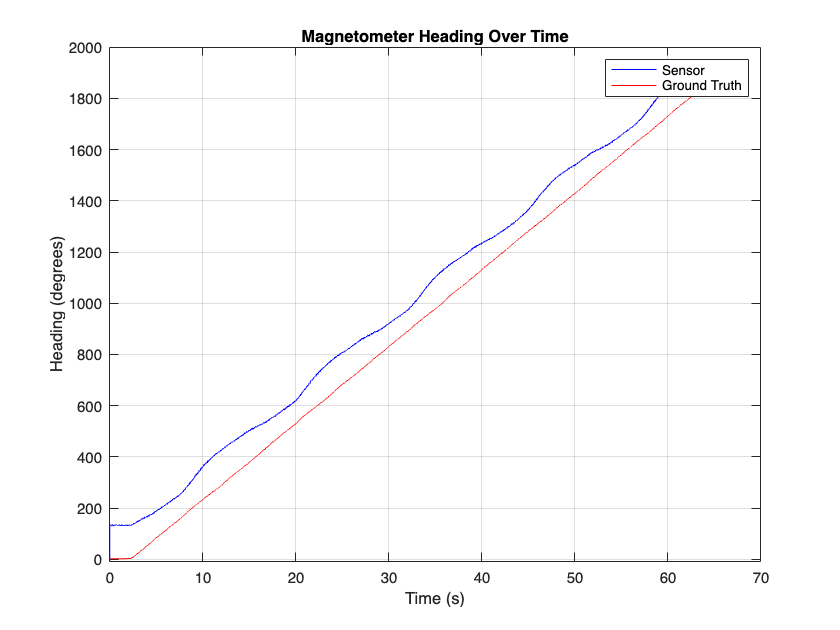


% Compare heading angle of sensor vs. ground truth
SS_heading_rad = atan2(mag_cal(:,2), mag_cal(:,1));
SS_heading_unwrapped = unwrap(SS_heading_rad);
SS_heading_deg = rad2deg(SS_heading_unwrapped);

q_GT = quaternion(GT_calib_rot);
eul = quat2eul(q_GT);
GT_heading_unwrapped = unwrap(eul(:,1));   % Smooth the angle discontinuities
GT_heading_deg = rad2deg(GT_heading_unwrapped);  % Back to degrees

figure;
plot(time_rot, SS_heading_deg, 'b', time_rot, abs(GT_heading_deg), 'r');
xlabel('Time (s)');
ylabel('Heading (degrees)');
title('Magnetometer Heading Over Time');
legend('Sensor', 'Ground Truth')
grid on;


% Calculate RMSE
heading_error = SS_heading_deg - GT_heading_deg;

% Optional: wrap to [-180, 180] if using circular data
heading_error = mod(heading_error + 180, 360) - 180;

rmse_heading = sqrt(mean(heading_error.^2));
fprintf('Heading RMSE: %.2f degrees\n', rmse_heading);

Heading RMSE: 108.31 degrees


#### Import Data: Ground Truth, Sensor

% Minimum can be done with 3 ToF and magnetometer
% More robust with additional sensors

% Ground Truth
GT_time = task1_1.out.GT_time.time;

% GT Position (X,Y,Z[m])
GT_pos = task1_1.out.GT_position.signals.values;
GT_rot = task1_1.out.GT_rotation.signals.values;

% Sensor inputs
% ToF = (Distance[m], Ambient[kcps/spad], Signal[kcps/spad], Status)
% Magnetometer = (X,Y,Z[T,teslas])
SS_ToF1 = task1_1.out.Sensor_ToF1.signals.values;
SS_ToF2 = task1_1.out.Sensor_ToF2.signals.values;
SS_ToF3 = task1_1.out.Sensor_ToF3.signals.values;
SS_magnet = task1_1.out.Sensor_MAG.signals.values;

#### Measure Position and Yaw with EKF (use calibrated sensors)

## Task 2: Circuit Course Drive

a. The robot drives a more complex path around the arena with varying velocity.

b. Exact path is known to you ahead of time (and differs across teams).

c. Your estimater must remain robust to changing velocity and direction.

function [mag_cal, params] = calibrateMagnetometer2D(mag_raw_2D)
% CALIBRATEMAGNETOMETER2D
% Performs nonlinear ellipse fitting and magnetometer calibration
% using centering, rotation, and normalization

% INPUT:
%   mag_raw_2D - Nx2 matrix of raw [X, Y] magnetometer data
% OUTPUT:
%   mag_cal    - Nx2 calibrated magnetometer data
%   params     - structure with fitted parameters

    epsilon = 1e-10;

    % Normalize for numerical stability
    mu = mean(mag_raw_2D);
    sigma = std(mag_raw_2D);
    mag_norm = (mag_raw_2D - mu) ./ sigma;

    % Initial guess [center_x, center_y, a, b, theta]
    x0 = 0; y0 = 0; a0 = 1; b0 = 1; theta0 = 0;
    p0 = [x0, y0, a0, b0, theta0];

    % Residual function: how far each point is from the ellipse surface
    residuals = @(p) ...
        ((( (mag_norm(:,1) - p(1)) * cos(p(5)) + (mag_norm(:,2) - p(2)) * sin(p(5))) / max(p(3), epsilon)).^2 + ...
         ((-(mag_norm(:,1) - p(1)) * sin(p(5)) + (mag_norm(:,2) - p(2)) * cos(p(5))) / max(p(4), epsilon)).^2 - 1);

    % Bounds to constrain optimization
    lb = [-2, -2, 0.1, 0.1, -pi];
    ub = [ 2,  2, 5.0, 5.0,  pi];

    % Optimization options
    opts = optimoptions('lsqnonlin', 'Display', 'off', 'MaxIterations', 1000);

    % Run optimization
    p_opt = lsqnonlin(residuals, p0, lb, ub, opts);

    % Extract parameters
    offset_norm = p_opt(1:2);
    a = max(p_opt(3), epsilon);
    b = max(p_opt(4), epsilon);
    theta = p_opt(5);

    % De-normalize center
    offset = offset_norm .* sigma + mu;

    % Construct rotation and scaling matrices
    R = [cos(theta), sin(theta); -sin(theta), cos(theta)];  % Rotation
    S = diag([1/a, 1/b]);                                   % Inverse scaling

    % Final transformation matrix (in normalized space)
    T_norm = S * R;

    % Apply calibration: center, normalize, rotate
    mag_centered = mag_raw_2D - offset;
    mag_cal = (T_norm * ((mag_centered ./ sigma)'))';  % Back to calibrated space

    % Output params
    params.offset = offset;
    params.softIronMatrix = T_norm;
    params.rotation = R;
    params.scaling = S;
    params.ellipse = p_opt;
end

% function [mag_cal, params] = calibrateEllipse2D(mag_raw_2D)
% % CALIBRATEELLIPSE2D Performs nonlinear ellipse calibration on 2D magnetometer data
% % Inputs:
% %   mag_raw_2D - Nx2 matrix of raw [X, Y] magnetometer readings
% % Outputs:
% %   mag_cal    - Nx2 matrix of calibrated magnetometer data
% %   params     - [x0, y0, a, b, theta] - estimated ellipse parameters
% 
%     % Initial parameter guess
%     x0 = mean(mag_raw_2D(:,1));
%     y0 = mean(mag_raw_2D(:,2));
%     a0 = std(mag_raw_2D(:,1));
%     b0 = std(mag_raw_2D(:,2));
%     theta0 = 0;
% 
%     params0 = [x0, y0, a0, b0, theta0];  % [center_x, center_y, a, b, theta]
% 
%     % Define residual function
%     ellipse_residual = @(p) ...
%         ((( (mag_raw_2D(:,1) - p(1)) * cos(p(5)) + (mag_raw_2D(:,2) - p(2)) * sin(p(5))) / p(3)).^2 + ...
%          ((-(mag_raw_2D(:,1) - p(1)) * sin(p(5)) + (mag_raw_2D(:,2) - p(2)) * cos(p(5))) / p(4)).^2 - 1);
% 
%     % Optimization options
%     opts = optimoptions('lsqnonlin', 'Display', 'off', 'MaxIterations', 1000);
% 
%     % Run nonlinear optimization
%     [params, ~] = lsqnonlin(ellipse_residual, params0, [], [], opts);
% 
%     % Extract parameters
%     center = params(1:2);    % [x0, y0]
%     a = params(3);
%     b = params(4);
%     theta = params(5);
% 
%     % Apply calibration
%     R = [cos(theta), sin(theta); -sin(theta), cos(theta)];  % Rotation
%     S = diag([1/a, 1/b]);                                   % Inverse scaling
%     T = S * R;                                              % Soft-iron correction
% 
%     mag_centered = mag_raw_2D - center;                     % Remove offset
%     mag_cal = (T * mag_centered')';                         % Calibrated output
% end

## Estimator Algorithm: Extended Kalman Filter (EKF)